# ANOVA test

Clear workspace

clear all; clc; close all;

## Aux (just to plot the distribution with more data)

### Initialize data

aux = 3*rand(50000,1);
purchase_amt = zeros(50000,1);
offers = cell(50000,1);
offers_int = zeros(50000,1);
for ii = 1:length(aux)
    if aux(ii) < 1
        offers{ii} = "offer1";
        offers_int(ii) = 1;
        purchase_amt(ii) = normrnd(80,30);
    elseif aux(ii) < 2
        offers{ii} = "offer2";
        offers_int(ii) = 2;
        purchase_amt(ii) = normrnd(85,30);
    else
        offers{ii} = "nooffer";
        purchase_amt(ii) = normrnd(40,30);
    end
end

purchase_amt(purchase_amt<0) = 0;

Check that we have no negative values

min(purchase_amt)

ans = 0

% Number of values corrected to 0
numel(purchase_amt(purchase_amt==0))

ans = 1647

### Explore data

Plot the distributions

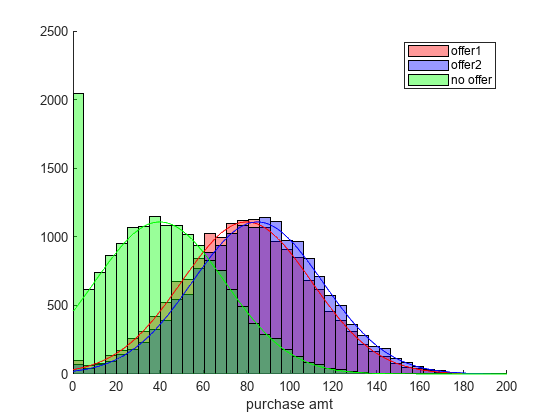

binedges = linspace(0, ceil(max(purchase_amt)), ceil(max(purchase_amt)/5));

figure(1)
hold on
h1 = histogram(purchase_amt(offers_int==1), 'BinEdges', binedges, FaceColor='r', FaceAlpha=0.4);
h2 = histogram(purchase_amt(offers_int==2), 'BinEdges', binedges, FaceColor='b', FaceAlpha=0.4);
h3 = histogram(purchase_amt(offers_int==0),'BinEdges', binedges, FaceColor='g', FaceAlpha=0.4);
plot([0:.5:200],50000/3*5*normpdf([0:.5:200],80,30),'r-')
plot([0:.5:200],50000/3*5*normpdf([0:.5:200],85,30),'b-')
plot([0:.5:200],50000/3*5*normpdf([0:.5:200],40,30),'g-')
xlim([0,200])
xlabel('purchase amt')
hold off
legend('offer1','offer2','no offer')
saveas(gcf,'01_ANOVA/ANOVA_hist_2.png')

## Initialize variables

aux = 3*rand(500,1);
purchase_amt = zeros(500,1);
offers = cell(500,1);
offers_int = zeros(500,1);
for ii = 1:length(aux)
    if aux(ii) < 1
        offers{ii} = "offer1";
        offers_int(ii) = 1;
        purchase_amt(ii) = normrnd(80,30);
    elseif aux(ii) < 2
        offers{ii} = "offer2";
        offers_int(ii) = 2;
        purchase_amt(ii) = normrnd(85,30);
    else
        offers{ii} = "nooffer";
        purchase_amt(ii) = normrnd(40,30);
    end
end

purchase_amt(purchase_amt<0) = 0;

Check that we have no negative values

min(purchase_amt)

ans = 0

% Number of values corrected to 0
numel(purchase_amt(purchase_amt==0))

ans = 13

## Explore data

Plot the distributions

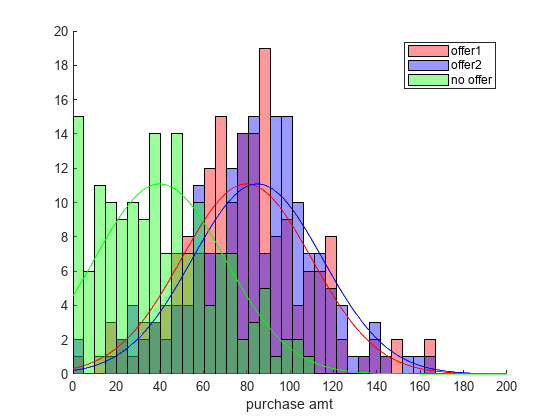

binedges = linspace(0, ceil(max(purchase_amt)), ceil(max(purchase_amt)/5));

figure(2)
hold on
h1 = histogram(purchase_amt(offers_int==1), 'BinEdges', binedges, FaceColor='r', FaceAlpha=0.4);
h2 = histogram(purchase_amt(offers_int==2), 'BinEdges', binedges, FaceColor='b', FaceAlpha=0.4);
h3 = histogram(purchase_amt(offers_int==0),'BinEdges', binedges, FaceColor='g', FaceAlpha=0.4);
plot([0:.5:200],500/3*5*normpdf([0:.5:200],80,30),'r-')
plot([0:.5:200],500/3*5*normpdf([0:.5:200],85,30),'b-')
plot([0:.5:200],500/3*5*normpdf([0:.5:200],40,30),'g-')
xlim([0,200])
xlabel('purchase amt')
hold off
legend('offer1','offer2','no offer')
saveas(gcf,'01_ANOVA/ANOVA_hist_1.png')

## ANOVA tests

### MATLAB built-in function

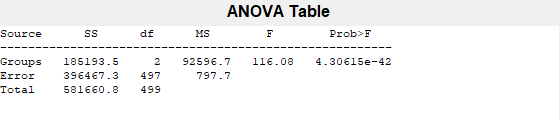

p = 4.3061e-42

tbl = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'F'       }    {'Prob>F'    }
    {'Groups'}    {[1.8519e+05]}    {[  2]}    {[9.2597e+04]}    {[116.0766]}    {[4.3061e-42]}
    {'Error' }    {[3.9647e+05]}    {[497]}    {[  797.7209]}    {0×0 double}    {0×0 double  }
    {'Total' }    {[5.8166e+05]}    {[499]}    {0×0 double  }    {0×0 double}    {0×0 double  }


stats = struct with fields:
    gnames: {3×1 cell}
         n: [156 175 169]
    source: 'anova1'
     means: [40.3237 79.6492 83.8138]
        df: 497
         s: 28.2440


% a = purchase_amt(offers_int==1);
% b = purchase_amt(offers_int==2);
% c = purchase_amt(offers_int==0);
% 
% n = min([size(a,1),size(b,1),size(c,1)])
% 
% [p, tbl, stats] = anova1([a(1:n) b(1:n) c(1:n)])
% 
% multcompare(stats)

[p, tbl, stats] = anova1(purchase_amt(:),offers_int(:))

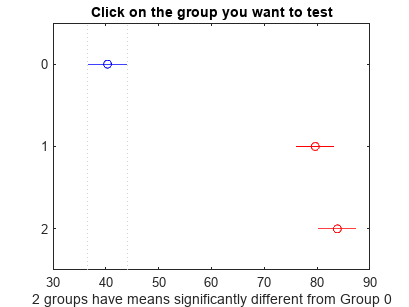

ans =     1.0000    2.0000  -46.6144  -39.3255  -32.0366         0
    1.0000    3.0000  -50.8397  -43.4901  -36.1405         0
    2.0000    3.0000  -11.3037   -4.1645    2.9746    0.3582



multcompare(stats)

### Explicit computation

X = purchase_amt;
groups = offers_int;

diff_groups = unique(groups);
k = size(diff_groups,1);
n = size(offers,1);

% Compute Means
mean_all = mean(X);
mean_between = zeros(k,1);
n_group = zeros(k,1);
for ii = 1:k
    mean_between(ii) = mean(X(groups==diff_groups(ii)));
    for jj = 1:n
        if X(groups(jj)==diff_groups(ii))
            n_group(ii) = n_group(ii) + 1;
        end
    end
end

% Between samples row
dfb = k-1;
SSb = 0;
for ii = 1:k
    SSb = SSb + n_group(ii)*(mean_between(ii) - mean_all)^2;
end
MSb = SSb/dfb;

% Within samples row
dfw = n - k;
SSw = 0;
for ii = 1:n
    for jj = 1:k
        if groups(ii) == diff_groups(jj)
            SSw = SSw + (mean_between(jj) - X(ii))^2;
        end
    end
end
MSw = SSw/dfw;

% Total row
SSt = SSb + SSw;
df = n - 1;

% F-static
F = MSb/MSw

F = 116.0766


% p>F
p = fcdf(F,dfb,dfw,'upper')

p = 4.3061e-42


Source = ['Group'; 'Error'; 'Total'];
SS = [SSb; SSw; SSt];
df = [dfb; dfw; df];
MS = [MSb; MSw; 0];
F_ = [F; 0; 0];
prob_F = [p; 0; 0];

anova = table(Source, SS, df, MS, F_, prob_F)

anova = 3×6 table
    Source        SS        df       MS        F_        prob_F  
    ______    __________    ___    ______    ______    __________

    Group     1.8519e+05      2     92597    116.08    4.3061e-42
    Error     3.9647e+05    497    797.72         0             0
    Total     5.8166e+05    499         0         0             0


### Avoiding loops


diff_groups = unique(offers_int);
k = size(diff_groups,1);
n = size(offers,1);

dfb = k-1;
dfw = n - k;
df = n - 1;

a = purchase_amt(offers_int==0);
b = purchase_amt(offers_int==1);
c = purchase_amt(offers_int==2);

SSb = ((size(a,1)*(mean(a)-mean([a;b;c]))^2 + ...
        size(b,1)*(mean(b)-mean([a;b;c]))^2 + ...
        size(c,1)*(mean(c)-mean([a;b;c]))^2 ));
SSw = ( (size(a,1)-1) * var(a) + ...
        (size(b,1)-1) * var(b) + ...
        (size(c,1)-1) * var(c) );
SSt = SSb + SSw;

MSb = SSb/dfb;
MSw = SSw/dfw;

F = MSb/MSw

F = 116.0766

p = fcdf(F,dfb,dfw,'upper')

p = 4.3061e-42

f = figure(5)

f =   Figure (EmbeddedFigure_Internal) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [403 246 560 420]
       Units: 'pixels'

  Show all properties


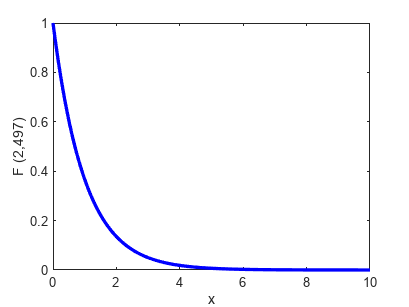

plot([0:0.01:10],fpdf([0:0.01:10],dfb,dfw),'b',LineWidth=2.5)
ylabel(strcat('F (',num2str(dfb),',',num2str(dfw),')'))
xlabel('x')
saveas(gcf,'01_ANOVA/f_distrib.png')


Source = ['Group'; 'Error'; 'Total'];
SS = [SSb; SSw; SSt];
df = [dfb; dfw; df];
MS = [MSb; MSw; 0];
F_ = [F; 0; 0];
prob_F = [p; 0; 0];

anova = table(Source, SS, df, MS, F_, prob_F)

anova = 3×6 table
    Source        SS        df       MS        F_        prob_F  
    ______    __________    ___    ______    ______    __________

    Group     1.8519e+05      2     92597    116.08    4.3061e-42
    Error     3.9647e+05    497    797.72         0             0
    Total     5.8166e+05    499         0         0             0


stats = struct;
stats.gnames={'No Offer', 'Offer 1', 'Offer 2'}';
stats.n=[size(a,1), size(b,1), size(c,1)];
stats.source='anova1';
stats.means= [mean(a), ...
              mean(b), ...
              mean(c) ];
stats.df= dfw;
stats.s=mean([std(a), ...
              std(b), ...
              std(c)]);

stats

stats = struct with fields:
    gnames: {3×1 cell}
         n: [156 175 169]
    source: 'anova1'
     means: [40.3237 79.6492 83.8138]
        df: 497
         s: 28.1769


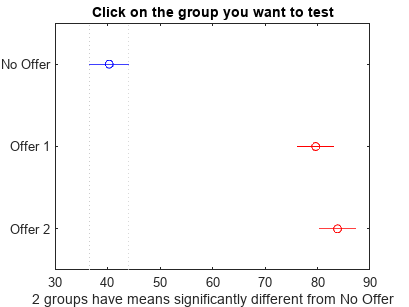

ans =     1.0000    2.0000  -46.5971  -39.3255  -32.0539         0
    1.0000    3.0000  -50.8222  -43.4901  -36.1579         0
    2.0000    3.0000  -11.2867   -4.1645    2.9576    0.3565



multcompare(stats)